# Final Project Implementation/Demonstration

## LSB Encoding - Basics

LSB encoding is a technique that uses the smallest least significant bit (LSB) of a sequence of samples to convey data, essentially hiding a secondary data stream in the place where interference is least likely to result. 

clc; close all
%obtain our audio sample of 1 minute
[audio, Fs] = audioread("CantinaBand60.wav", 'native');

%signal to be concealed and how many times to play it
hidden_msg = ['I am a hidden message. You cannot see me, or can you? Repeat: ' newline];
%for demo's sake, fill up the whole file
repetitions = floorDiv(length(audio),length(hidden_msg)*8); 

%convert string to a bitstream
tx_bitstream = makestream_string(repmat(hidden_msg, 1, repetitions))

tx_bitstream = '010010010010000001100001011011010010000001100001001000000110100001101001011001000110010001100101011011100010000001101101011001010111001101110011011000010110011101100101001011100010000001011001011011110111010100100000011000110110000101101110011011100110111101110100001000000111001101100101011001010010000001101101011001010010110000100000011011110111001000100000011000110110000101101110001000000111100101101111011101010011111100100000010100100110010101110000011001010110000101110100001110100010000000001010010010010010000001100001011011010010000001100001001000000110100001101001011001000110010001100101011011100010000001101101011001010111001101110011011000010110011101100101001011100010000001011001011011110111010100100000011000110110000101101110011011100110111101110100001000000111001101100101011001010010000001101101011001010010110000100000011011110111001000100000011000110110000101101110001000000111100101101111011101010011111100100000010100100110010101110000011001010110000101110100

number_of_bits = length(tx_bitstream)

number_of_bits = 1323000

number_of_samples = length(audio)

number_of_samples = 1323000

data_rate = Fs

data_rate = 22050

Because LSB encoding allows us to add transmit one bit per sample, our data rate is equal to our sample rate. This can be increased by using more than just the LSB. Using the N least significant bits can increase the data rate at the cost of increaasing distortion. 

%generate a new audio vector using function
output = encode_audiostream_1D(audio, tx_bitstream);
audiowrite('secret_message.wav', output, Fs)
seconds_to_play = 5;
player = audioplayer(audio(1:seconds_to_play*Fs), Fs);
%play(player)

%extract the hidden message
LSBytes = extractLSB(output, 8);
char(LSBytes)

ans =     'I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see me, or can you? Repeat: 
     I am a hidden message. You cannot see

## Increasing Data Rate

Now that we have a method for encoding arbitrary binary streams into the LSB of a signal, we can apply permutations of this technique to do some more interesting things. The first thing we can try to do is increase the data rate. This project uses an example of CD-quality bit depth, or 16-bit audio. We heard very little distortion with only the LSB of the audio being affected, but what about using the 2 least significant bits (LSBs)? 4? Even more? We first need to rewrite our functions to handle this variable.

clear;
[audio, Fs] = audioread("CantinaBand60.wav", 'native');

%2x Sample rate, 2 LSBs
hidden_msg = ['How fast can we go? 2xFs bps Repeat: ' newline];
num_LSBs = 2; %number of LSBs to use

%create a bitstream for the whole file
repetitions = floorDiv(length(audio)*num_LSBs,length(hidden_msg)*8); 
tx_bitstream = makestream_string(repmat(hidden_msg, 1, repetitions))
length(audio)*num_LSBs
length(tx_bitstream)

%encode
output = encode_audiostream_ND(audio, tx_bitstream, num_LSBs);

%play
seconds_to_play = 5;
player = audioplayer(output(1:seconds_to_play*Fs), Fs);
%play(player)

%decode
LSBytes = extract_N_LSB(output, 8, num_LSBs);
char(LSBytes)
audiowrite('secret_cantina_2LSBs.wav', output, Fs)

This sounds fine to my ears. Empirically, it starts to get very noticeable around 10 bits. Let's generate some more wavs

clear;
[audio, Fs] = audioread("CantinaBand60.wav", 'native');

%6x Sample rate, 6 LSBs
hidden_msg = ['How fast can we go? 6xFs bps Repeat: ' newline];
num_LSBs = 6; %number of LSBs to use

%create a bitstream for the whole file
repetitions = floorDiv(length(audio)*num_LSBs,length(hidden_msg)*8); 
tx_bitstream = makestream_string(repmat(hidden_msg, 1, repetitions))
length(audio)*num_LSBs
length(tx_bitstream)

%encode
output = encode_audiostream_ND(audio, tx_bitstream, num_LSBs);

%play
seconds_to_play = 5;
player = audioplayer(output(1:seconds_to_play*Fs), Fs);
%play(player)

%decode
LSBytes = extract_N_LSB(output, 8, num_LSBs);
char(LSBytes)
audiowrite('secret_cantina_6LSBs.wav', output, Fs)

9 bits

clear;
[audio, Fs] = audioread("CantinaBand60.wav", 'native');

%9x Sample rate, 9 LSBs
hidden_msg = ['How fast can we go? 9xFs bps Repeat: ' newline];
num_LSBs = 9; %number of LSBs to use

%create a bitstream for the whole file
repetitions = floorDiv(length(audio)*num_LSBs,length(hidden_msg)*8); 
tx_bitstream = makestream_string(repmat(hidden_msg, 1, repetitions))
length(audio)*num_LSBs
length(tx_bitstream)

%encode
output = encode_audiostream_ND(audio, tx_bitstream, num_LSBs);

%play
seconds_to_play = 5;
player = audioplayer(output(1:seconds_to_play*Fs), Fs);
%play(player)

%decode
LSBytes = extract_N_LSB(output, 8, num_LSBs);
char(LSBytes)
audiowrite('secret_cantina_9LSBs.wav', output, Fs)

10 bits

clear;
[audio, Fs] = audioread("CantinaBand60.wav", 'native');

%10x Sample rate, 10 LSBs
hidden_msg = ['How fast can we go? 10xFs bps Repeat: ' newline];
num_LSBs = 10; %number of LSBs to use

%create a bitstream for the whole file
repetitions = floorDiv(length(audio)*num_LSBs,length(hidden_msg)*8); 
tx_bitstream = makestream_string(repmat(hidden_msg, 1, repetitions))
length(audio)*num_LSBs
length(tx_bitstream)

%encode
output = encode_audiostream_ND(audio, tx_bitstream, num_LSBs);

%play
seconds_to_play = 5;
player = audioplayer(output(1:seconds_to_play*Fs), Fs);
%play(player)

%decode
LSBytes = extract_N_LSB(output, 8, num_LSBs);
char(LSBytes)
audiowrite('secret_cantina_10LSBs.wav', output, Fs)

12 bits, quite distorted

[audio, Fs] = audioread("CantinaBand60.wav", 'native');

%12x Sample rate, 12 LSBs
hidden_msg = ['How fast can we go? 12xFs bps Repeat: ' newline];
num_LSBs = 12; %number of LSBs to use

%create a bitstream for the whole file
repetitions = floorDiv(length(audio)*num_LSBs,length(hidden_msg)*8); 
tx_bitstream = makestream_string(repmat(hidden_msg, 1, repetitions))
length(audio)*num_LSBs
length(tx_bitstream)

%encode
output = encode_audiostream_ND(audio, tx_bitstream, num_LSBs);

%play
seconds_to_play = 5;
player = audioplayer(output(1:seconds_to_play*Fs), Fs);
%play(player)

%decode
LSBytes = extract_N_LSB(output, 8, num_LSBs);
char(LSBytes)
audiowrite('secret_cantina_12LSBs.wav', output, Fs)

## Encoding More Interesting Data

In the above section we proved out an implementation of LSB encoding with arbitrary bitstreams and bit-depth, but when we're just sending text all we can do to show off the data rate is repeat the message many times. What if we wanted to send something more interesting? An image is a fun visual piece of information, and also takes far more data than text to represent.  Let's use a classic DSP image of peppers for this.

Source for images: Queen Mary University of London

clear
%take a look at our peppers

pep = 512×512 uint8 matrix
     5    65    67    57    66    60    57    55    58    61    66    72    76    78    79    79    84    79    78    81    82    80    80    83    82    79    80    86    86    81    80    83    83    81    81    85    85    81    80    82    86    80    84    86    80    82    86    80    78    84
    20    84    89    79    88    84    82    81    85    85    85    84    83    80    78    77    83    79    78    80    82    80    81    85    80    77    78    83    83    78    77    80    84    80    79    82    82    80    81    85    89    82    85    86    79    81    85    79    76    79
    20    88    97    86    93    88    87    87    88    88    88    87    85    84    82    81    84    79    78    80    80    79    82    86    80    78    78    81    81    78    77    79    84    80    77    79    80    79    82    88    87    80    82    82    74    76    80    75    77    78
    14    86    96    82    86    80    79    78    78    80    83    

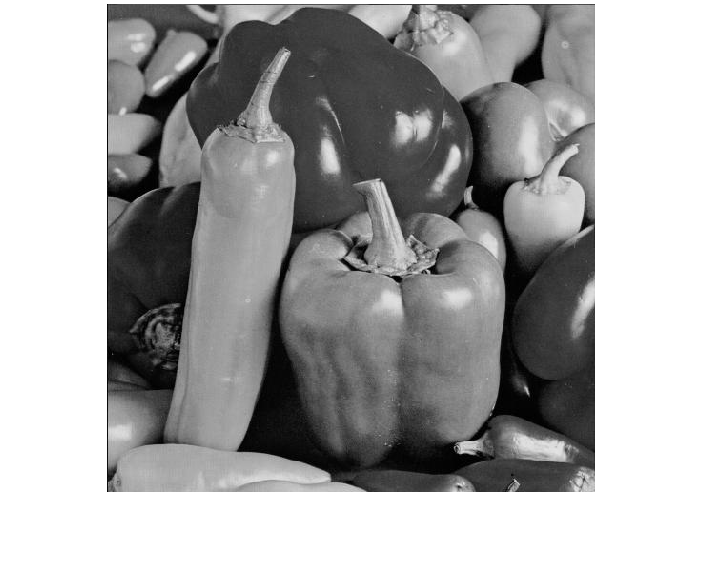

imshow(pep)

Peppers is a 512*512 greyscale tiff with 8 bits of depth. Let's calculate the size of an audio file needed to transmit it using a single LSB. Remember: the data rate is dependent on the sample rate of the audio.

[audio, Fs] = audioread("CantinaBand60.wav", 'native');
bits_in_image = 512*512 * 8

bits_in_image = 2097152

length(audio)

ans = 1323000

It looks like our image contains more bits than our audio has samples. This means we will need to either compress the data, or utilize more LSBs to store it. Because we already have a method of using more LSBs, let's try that. Compression, encryption, and forward error correction are commonly used in stenography but we can save those for another time. 

%first we need to serialize the image
pep = imread('peppers.tif') 
binary_pep = dec2bin(pep);
binary_pep = reshape(binary_pep.', 1, []); %1s and 0s

%now embed into audio using our past function. We can use 2 for LSB
num_LSBs = 2;
peppered_song = encode_audiostream_ND(audio, binary_pep, num_LSBs);
audiowrite('peppered_cantina.wav', peppered_song, Fs)

%play a sample
seconds_to_play = 5;
player = audioplayer(peppered_song(1:seconds_to_play*Fs), Fs);
%play(player)

%extract serialized image bytes
serialized_pep = extract_N_LSB(peppered_song, 8, num_LSBs)

serialized_pep =      5    20    20    14    17    13     9    14    10    11    11    10     8     6     7     8     2     0     0     2     6     6     1     0     6     6     6     6     7     7     7     7     3     2     2     3     5     8    10    12    14    14    14    13    11     9     7     5     0     1


%we know how many bytes we are looking for
bytes_in_image = 512*512;
serialized_pep = serialized_pep(1:bytes_in_image)

serialized_pep =      5    20    20    14    17    13     9    14    10    11    11    10     8     6     7     8     2     0     0     2     6     6     1     0     6     6     6     6     7     7     7     7     3     2     2     3     5     8    10    12    14    14    14    13    11     9     7     5     0     1


reconstructed_pepper = reshape(uint8(serialized_pep), [512, 512])

reconstructed_pepper = 512×512 uint8 matrix
     5    65    67    57    66    60    57    55    58    61    66    72    76    78    79    79    84    79    78    81    82    80    80    83    82    79    80    86    86    81    80    83    83    81    81    85    85    81    80    82    86    80    84    86    80    82    86    80    78    84
    20    84    89    79    88    84    82    81    85    85    85    84    83    80    78    77    83    79    78    80    82    80    81    85    80    77    78    83    83    78    77    80    84    80    79    82    82    80    81    85    89    82    85    86    79    81    85    79    76    79
    20    88    97    86    93    88    87    87    88    88    88    87    85    84    82    81    84    79    78    80    80    79    82    86    80    78    78    81    81    78    77    79    84    80    77    79    80    79    82    88    87    80    82    82    74    76    80    75    77    78
    14    86    96    82    86    80    79    78    7

imshow(reconstructed_pepper)

function [hidden_bits] = makestream_string(message)
    %create a bitsream given a string of arbitrary length
    message = uint8(message);
    message = dec2bin(message);
    %Init array
    hidden_bits = [];
    
    %Loop
    for i = 1:length(message)
        binaryStr = message(i,:);
        
        %Make sure we have 8-bits for this. 
        if length(binaryStr) == 7
            paddedBinaryStr = ['0', binaryStr];
        else
            paddedBinaryStr = binaryStr;
        end

        
        %Append each bit to hidden_bits
        for j = 1:8
            bit = paddedBinaryStr(j);
            hidden_bits = [hidden_bits, bit];
        end
    end
end

function [output] = encode_audiostream_1D(audio, bitstream)
    %encode a bitstream into the LSB of an audio file
    for i = 1:length(bitstream)
        %set LSB to 0 so we can OR it
        %00...001 is -2 for int16
        audio(i) = bitand(audio(i), int16(-2));
        %set LSB using OR and the bitStream
        
        audio(i) = bitor(audio(i), typecast(uint16(bin2dec(bitstream(i))), 'int16'));
    end
    output = audio;
end

function [output] = encode_audiostream_ND(audio, bitstream, n_bits)
    %encode N-dimensionally
    %encode a bitstream into the N LSBs of an audio file
    zero_out = repmat('0', 1, n_bits);
    one_out = repmat('1', 1, 16-n_bits);
    binstr = [one_out zero_out];
    ander = typecast(uint16(bin2dec(binstr)), 'int16');
    audio=audio(1:floorDiv(length(bitstream),n_bits));


    for i = 1:length(audio)
        bit_idx_start = (i-1) * n_bits + 1; %3
        bit_idx_end = i*n_bits; %4
        %set LSBs to 0 so we can OR it
        %00...001 is -2 for int16
        audio(i) = bitand(audio(i), int16(ander));
        %set LSB using OR and the bitStream
        bitsection = bitstream(bit_idx_start:bit_idx_end);
        audio(i) = bitor(audio(i), typecast(uint16(bin2dec(bitsection)), 'int16'));
    end
    output = audio;
end

function [LsbByteArray] = extractLSB(audio,bits)
    %take the LSB from audio and chunk it into bytes the size of 
    %the bits argument.
    LSBarray = bitand(audio(1:end), int16(1));
    %only return the a number of bits that are divisible by data size
    LSBarray = LSBarray(1:floorDiv(length(LSBarray), bits)*bits);
    LSBarray = reshape(LSBarray, bits, []);
    %a lot going on in this one-liner, but boils down to
    %transposing the array and converting the 0s and 1s to 8 bit ints
    LsbByteArray = bin2dec(num2str(LSBarray'))';
end

function [LsbByteArray] = extract_N_LSB(audio,bits,num_LSBs)
    %take the LSB from audio and chunk it into bytes the size of 
    %the bits argument. Do this for N LSBs
    zero_out = repmat('0', 1, 16-num_LSBs);
    one_out = repmat('1', 1, num_LSBs);
    binstr = [zero_out one_out];

    LSBarray = dec2bin(bitand(audio(1:end), typecast(uint16(bin2dec(binstr)), 'int16')));
    %serialize the array and chop off anything that doesn't fit
    LSBarray = reshape(LSBarray.', 1, []);
    LSBarray = LSBarray(1:floorDiv(length(LSBarray), bits)*bits);
    %chunk it into 8-bit parts
    LSBarray = reshape(LSBarray', bits, []).';
    %convert to a number so we can cast the whole thing to char
    LSBarray = bin2dec(LSBarray)';
    LsbByteArray = LSBarray;
end